clc;
clear;
close all;

zeta = [20 30 40 50];
conductivity = [8 23 28 34];
coded = (zeta - 35) / 5;

% linear
A_linear = [ones(4, 1) coded'];
xls_linear = inv((A_linear' * A_linear)) * (A_linear' * conductivity')

xls_linear =    23.2500
    4.1500



% quadratic
A_quad = [ones(4, 1) coded' coded'.^2];
xls_quad = inv((A_quad' * A_quad)) * (A_quad' * conductivity')

xls_quad =    26.0625
    4.1500
   -0.5625



% cubic
A_cub = [ones(4, 1) coded' coded'.^2 coded'.^3];
xls_cub = inv((A_cub' * A_cub)) * (A_cub' * conductivity')

xls_cub =    26.0625
    2.2708
   -0.5625
    0.2292


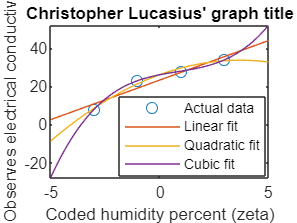


% plotting
x = linspace(-5, 5, 100);

y_linear = xls_linear(1) + xls_linear(2) .* x;
y_quad = xls_quad(1) + xls_quad(2) .* x + xls_quad(3) .* x.^2;
y_cub = xls_cub(1) + xls_cub(2) .* x + xls_cub(3) .* x.^2 + xls_cub(4) .* x.^3;

figure;
plot(coded, conductivity, 'o');
hold on;
plot(x, y_linear);
plot(x, y_quad);
plot(x, y_cub);
xlabel("Coded humidity percent (zeta)");
ylabel("Observes electrical conductivity");
legend("Actual data", "Linear fit", "Quadratic fit", "Cubic fit", location="best");
title("Christopher Lucasius' graph title")
hold off;